# Compare blood density with collagen parameter

It occurred to us that when there is a lot of blood, it can act in two ways.  First, as we model, it filters the spectral emissions.

Second, the blood also absorbs the excitation light.  So you might think that when the blood absorbs the excitation, the emissions will be lower.  

Thus, we thought to look at the blood density and ask whether the emission level was in fact lower when the blood density was high.

This was not really a necessary consequence because the blood density is high the emissions are already blocked quite a bit just by the first point, the spectral filtering.  So this look was just to see whether we might be able to separately judge whether the collagen weight was down as well when the spectral density was high.

The graph below shows that there is a trend for this correlation for 405/415 and even stronger for 450.

When the blood density is high the collagen and FAD estimates seem to be lower.  We don't see it within subjects, and the variance is pretty high within subject, so we decided that we probably don't have a good, independent estimate of the blood density versus the collagen weight.  They are probably too entangled.  High blood will knock the collagen no matter what.

## Initialize

ieInit;
wave = 500:700;
normWave = [];
yscale = 'linear';
odLevels = 1:1:40;
symbols = {'bs','rx','mo','g*'};
fise_plotDefaults;
subjects = oeSubjects;
[T,dataDir] = oeDatabaseCreate;

## Load up the lip data

Here, we load all of the subjects into a single large data set for tongue and another one for lip.  In this case we group the 405 and 415 nm excitation lights.  We put the tongue and lip data, normalized at nWave, on the same graph.

lipData = [];
for ii=1:numel(subjects)
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    tmp  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);   
    lipData = cat(2,lipData,tmp);
end 


lipData450 = [];
for ii=1:numel(subjects)
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    tmp  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);       
    lipData450 = cat(2,lipData450,tmp);
end 


## Create the fixed fluorophores

fluorophoreNamesB = {'collagen1-smooth','FAD_webfluor'};
[fixedFluorophores,wave] = fiLoadBasis(fluorophoreNamesB,'wave',wave);

## Fit the subjects individually - lip data

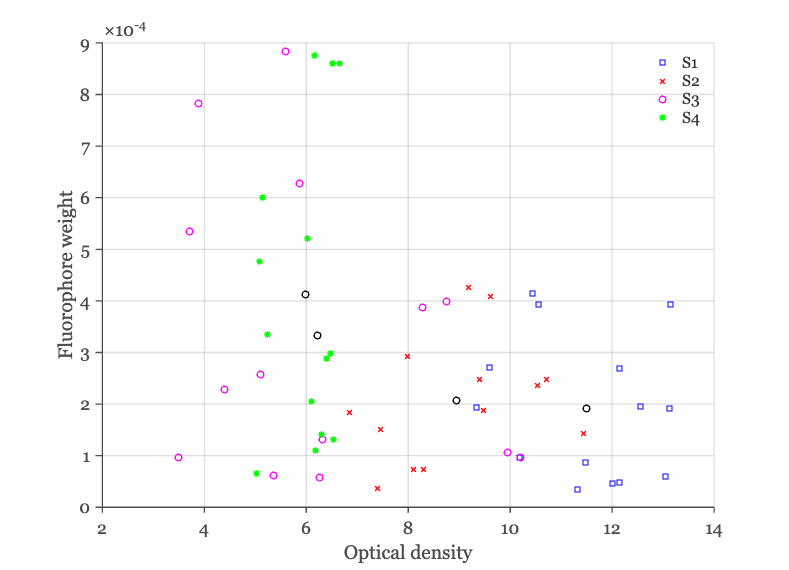

whichF = 2;   % Collagen = 1 and FAD = 2;

mnod = zeros(1,numel(subjects));
mnwgts = zeros(1,numel(subjects));
for ii=1:numel(subjects)   
    % Load the lip data
    files405 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',405);
    files415 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',415);
    lipFiles = cat(1,files405,files415);
    lipData  = oeReadFiles(lipFiles,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    odLip = zeros(1,size(lipData,2));
    err = size(odLip);
    weights = zeros(2,size(lipData,2));    
    for jj=1:size(lipData,2)
        [odLip(jj),weights(:,jj),finalFluorophores, err(jj)] = oeSolveBloodSingle(wave,lipData(:,jj),fixedFluorophores,'initialparameters',5);
    end

    if ii==1, ieFigure; hold on; end
    plot(odLip,weights(whichF,:),symbols{ii}); hold on;
    mnod(ii) = mean(odLip); mnwgts(ii) = mean(weights(whichF,:));

    % predicted = finalFluorophores*weights{ii};
    % nexttile;
    % plot(wave,predicted,'k--'); hold on;
    % plot(wave,lipData,'b-'); grid on;
    % xlabel('Wave (nm)'); ylabel('Fluorescence');
end
plot(mnod,mnwgts,'ko'); 
xlabel('Optical density'); 
if whichF == 1, ylabel('Collagen weight');
elseif whichF == 2, ylabel('Fluorophore weight'); 
end
grid on; legend({'S1','S2','S3','S4'});

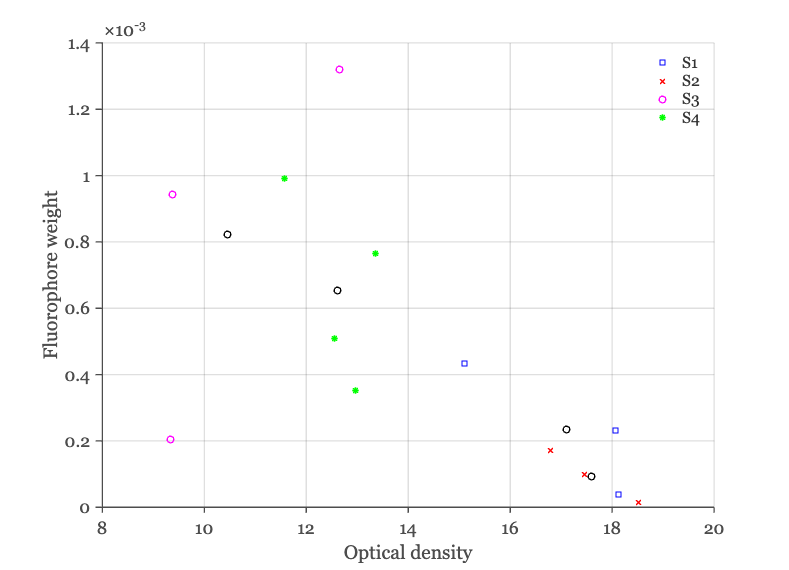

mnod = zeros(1,numel(subjects));
mnwgts = zeros(1,numel(subjects));
for ii=1:numel(subjects)   
    % Load the lip data
    files450 = ieTableGet(T,'subject',subjects{ii},'substrate','lip','e wave',450);
    lipData  = oeReadFiles(files450,'normalized wave',normWave,'wave',wave);

    % Find the blood optical density using only the first two columns of
    % saved fluorophores.
    odLip = zeros(1,size(lipData,2));
    err = size(odLip);
    weights = zeros(2,size(lipData,2));    
    for jj=1:size(lipData,2)
        [odLip(jj),weights(:,jj),finalFluorophores, err(jj)] = oeSolveBloodSingle(wave,lipData(:,jj),fixedFluorophores,'initialparameters',5);
    end

    if ii==1, ieFigure; hold on; end
    plot(odLip,weights(whichF,:),symbols{ii}); hold on;
    mnod(ii) = mean(odLip);mnwgts(ii) = mean(weights(whichF,:));

    % predicted = finalFluorophores*weights{ii};
    % nexttile;
    % plot(wave,predicted,'k--'); hold on;
    % plot(wave,lipData,'b-'); grid on;
    % xlabel('Wave (nm)'); ylabel('Fluorescence');
end
plot(mnod,mnwgts,'ko'); 
xlabel('Optical density'); 
if whichF == 1, ylabel('Collagen weight');
elseif whichF == 2, ylabel('Fluorophore weight'); 
end
grid on; legend({'S1','S2','S3','S4'});